# ¿Dónde está Wally?

**1 Borrar toda ventana o variable abierta**

clear; clc;
close all

**2 Cargar las Imágenes**

Escena = imread("Pikachu.png");
if true
    Wally = imread("Pikachu2.png"); 
else 
    Wally = imread('WallyFoto.jpg');
end

**3 Utilizar Función de **[**montage**](https://la.mathworks.com/help/images/ref/montage.html) 

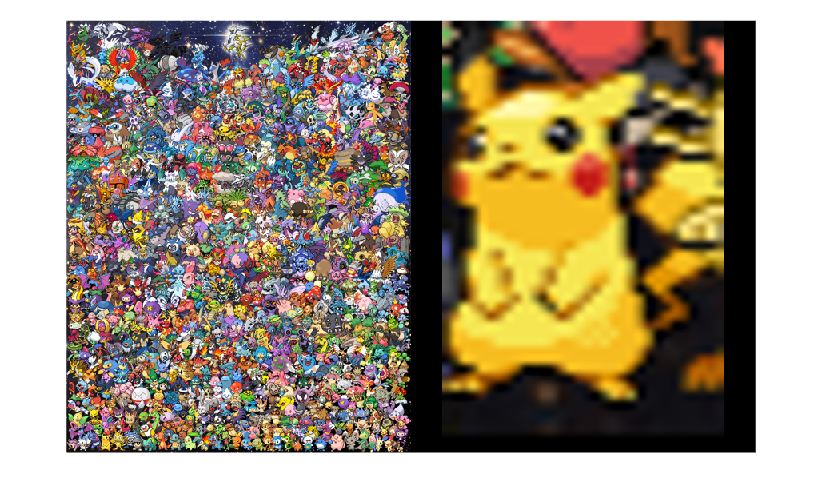

montage({Escena,Wally})

**4 Calcular la Correlación Cruzada de la escena con  respecto al patrón**

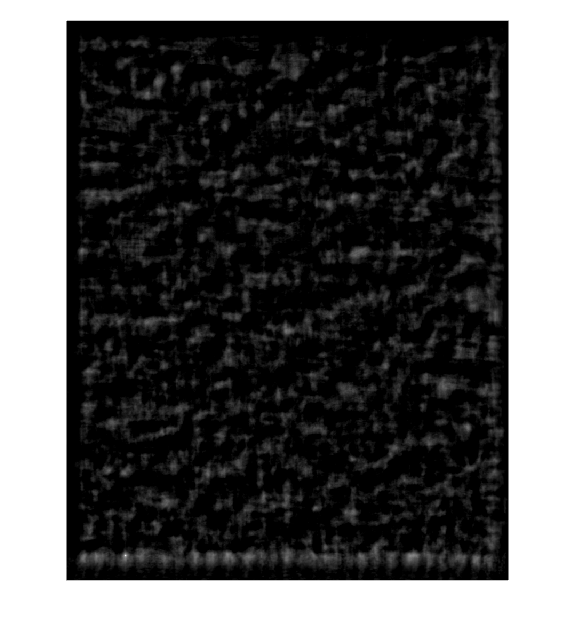

c = normxcorr2(Wally(:,:,1),Escena(:,:,1));
imshow(uint8(c*255))

**5 Calcular y mostrar dónde está la máxima correlación entre el esenario y el patrón**

[max_c, imax] = max(abs(c(:)))

max_c = 0.9663

imax = 116282

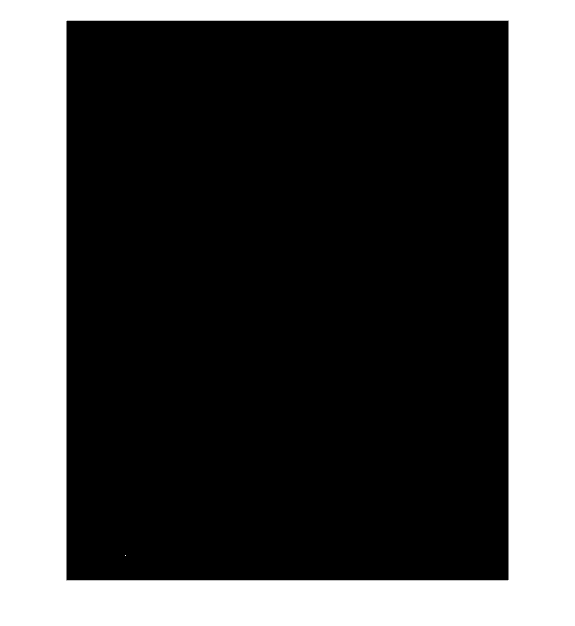

imshow(uint8((c) == max_c)*255)

**6 Encontrar dónde están la máxima correlación en un plano bidimensional**

[ypeak, xpeak] = ind2sub(size(c),imax(1))

ypeak = 1002

xpeak = 111

**7 Ajustar el desplazamiento de la imagen patrón**

if true
    corr_offset = [(xpeak-size(Wally,2)) (ypeak-size(Wally,1))]  %offset columnas-filas para centar a Wally
else
    corr_offset = [(xpeak) (ypeak)]
end

corr_offset =     79   953


**8 Mostrar los resultados sobre la imagen del escenario**

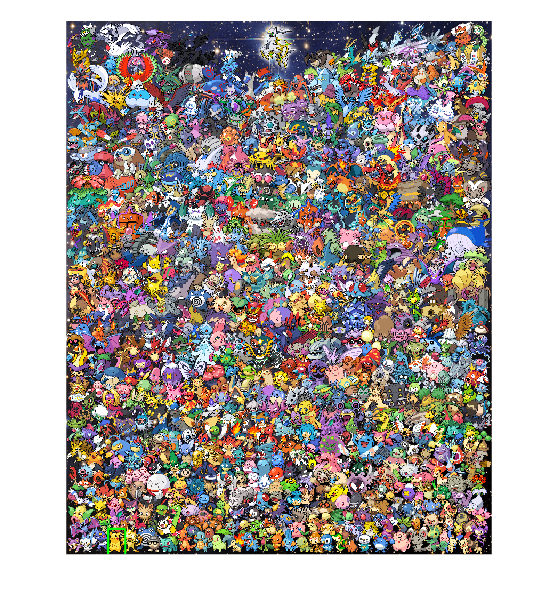



figure, imshow(Escena); hold on;
rectangle('position',[corr_offset(1) corr_offset(2) size(Wally,2) size(Wally,1)],...
          'curvature',[0.01,0.01],'edgecolor','g','linewidth',2);
hold off

**9 Repetir el ejercicio, es decir, modificar este Live Script para procesar al menos 5 imágenes en total de otros escenarios de *****¿donde está Wally?***